# Recitation 5 Post Problems

Leo Berman

clear;
clc;
close all;
syms s t w;

## 10.3.3

% Knowns
m = 200; %kg
k = 1800; %N/m

% converting into circuit
C = m;
L = 1/k;

% converting to s
Zc = 1/(C*s);
Zl = L*s;

% a. circuit representation

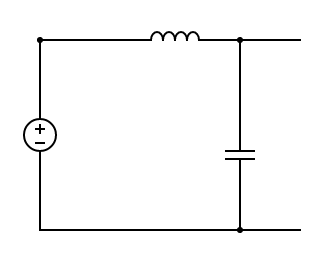

% b. Transfer Function
transfer_function = simplify(Zc/(Zl+Zc))

$$transfer\_function = \frac{9}{s^{2}+9}$$


% c. Impulse Response
impulse_response = ilaplace(transfer_function)*heaviside(t)

$$impulse\_response = 3\,\sin\left(3\,t\right)\,\mathrm{heaviside}\left(t\right)$$


% d. Frequency Response
frequency_response = simplify(subs(transfer_function,s,j*w))

$$frequency\_response = -\frac{9}{w^{2}-9}$$


% e. Convolve cos(3t)u(t)
x = cos(3*t)*heaviside(t);
convolution = ilaplace(laplace(impulse_response)*laplace(x))*heaviside(t)

$$convolution = \frac{3\,t\,\sin\left(3\,t\right)\,\mathrm{heaviside}\left(t\right)}{2}$$

## 10.3.4

% knowns
m = 200; % kg
ShockAbsorber1 = 600; % N*s/m
ShockAbsorber2 = 400; % N*s/m

% converting to circuit
C = m;
R1 = 1/ShockAbsorber1;
R2 = 1/ShockAbsorber2;

% a. circuit representation

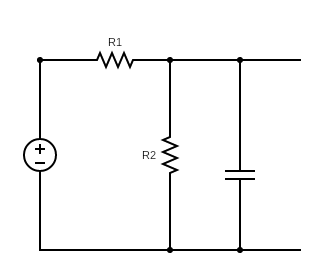


% converting to s domain
Zc = 1/(C*s);
Zr1 = R1;
Zr2 = R2;

Zcr2 = (1/Zc+1/Zr2)^-1;

% b. transfer function
transfer_function = simplify(Zcr2/(Zcr2+Zr1))

$$transfer\_function = \frac{3}{s+5}$$


% c. impulse response
impulse_response = simplify(ilaplace(transfer_function)*heaviside(t))

$$impulse\_response = 3\,{\mathrm{e}}^{-5\,t}\,\mathrm{heaviside}\left(t\right)$$


% d. frequency response
frequency_response = simplify(subs(impulse_response,s,j*w))

$$frequency\_response = 3\,{\mathrm{e}}^{-5\,t}\,\mathrm{heaviside}\left(t\right)$$


% e. convolution
x = exp(-5*t)*heaviside(t);
convolution = ilaplace(transfer_function*laplace(x))*heaviside(t)

$$convolution = 3\,t\,{\mathrm{e}}^{-5\,t}\,\mathrm{heaviside}\left(t\right)$$

## 10.3.7

% a. circuit representation

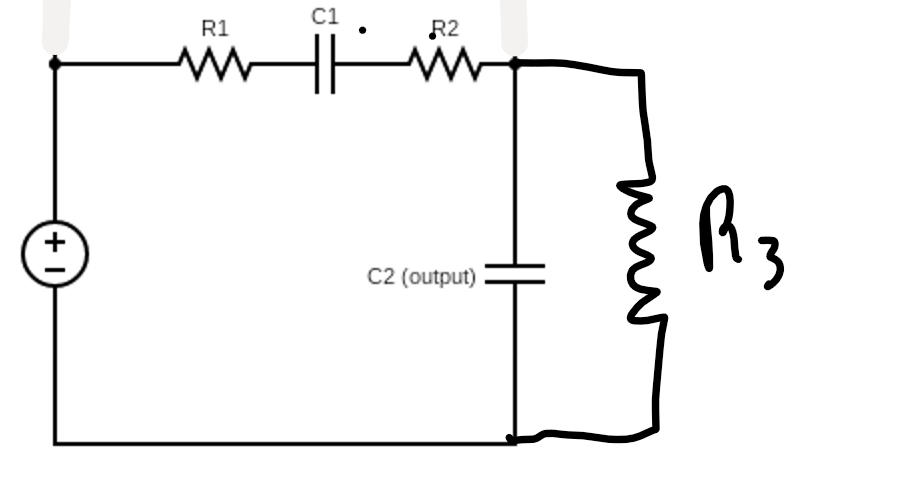

% knowns
shock1 = 200; % N * s / m
shock2 = 600; % N * s / m
shock3 = 300; % N * s / m
m1 = 200; % kg
m2 = 300; % kg

% converting to circuit
R1 = 1/shock1; %ohms
R2 = 1/shock2; %ohms
R3 = 1/shock3; %ohms
C1 = m1; %Farads
C2 = m2;

% converting to s domain
Zr1 = R1;
Zr2 = R2;
Zr3 = R3;
Zc1 = 1/(C1*s);
Zc2 = 1/(C2*s);


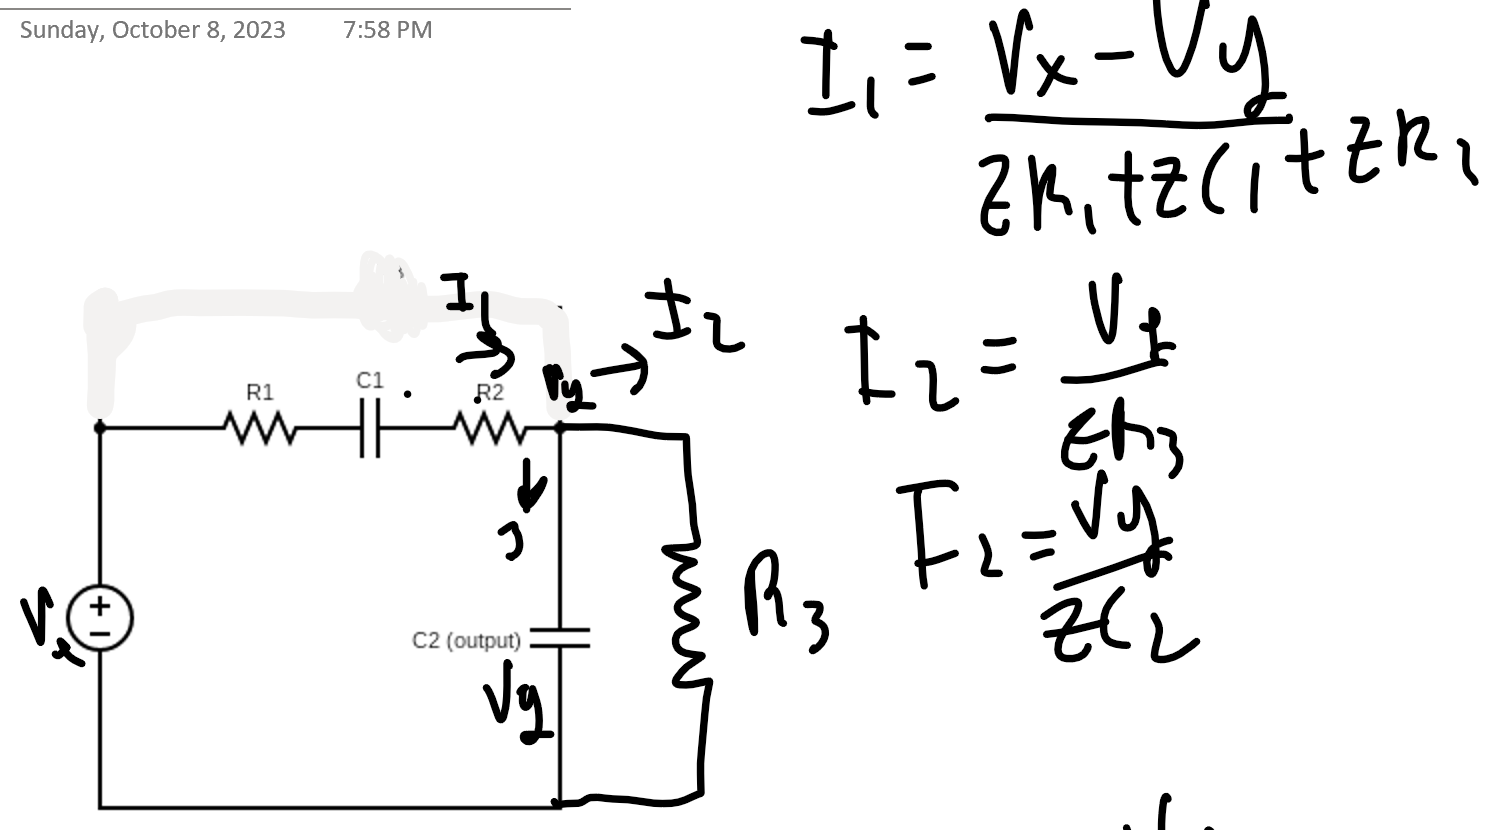

syms I1 I2 I3 Vy
Vx = 1;
eq1 = I1 == I2 + I3;
eq2 = I1 == (Vx-Vy)/(Zr1 + Zr2 + Zc1);
eq3 = I2 == Vy/R3;
eq4 = I3 == Vy/Zc2;
symssolve = [I1 I2 I3 Vy];
eqs = [eq1 eq2 eq3 eq4];
sol = solve(eqs,symssolve);
% b. transfer function
transfer_function=simplify(sol.Vy)

$$transfer\_function = \frac{2\,s}{4\,s^{2}+9\,s+3}$$


% c. impulse response
impulse_response = simplify(heaviside(t)*ilaplace(transfer_function))

$$impulse\_response = \frac{{\mathrm{e}}^{-\frac{9\,t}{8}}\,\mathrm{heaviside}\left(t\right)\,\left(\cosh\left(\frac{\sqrt{33}\,t}{8}\right)-\frac{3\,\sqrt{33}\,\sinh\left(\frac{\sqrt{33}\,t}{8}\right)}{11}\right)}{2}$$


% d. frequency response
frequency_response = simplify(subs(impulse_response,j*w))

$$frequency\_response = \frac{\mathrm{heaviside}\left(w\,\mathrm{i}\right)\,\left(\cos\left(\frac{9\,w}{8}\right)-\sin\left(\frac{9\,w}{8}\right)\,\mathrm{i}\right)\,\left(\cos\left(\frac{\sqrt{33}\,w}{8}\right)-\frac{3\,\sqrt{33}\,\sin\left(\frac{\sqrt{33}\,w}{8}\right)\,\mathrm{i}}{11}\right)}{2}$$

## 10.3.9 NOT FOR GRADING FOR MY USE

% a. circuit representation

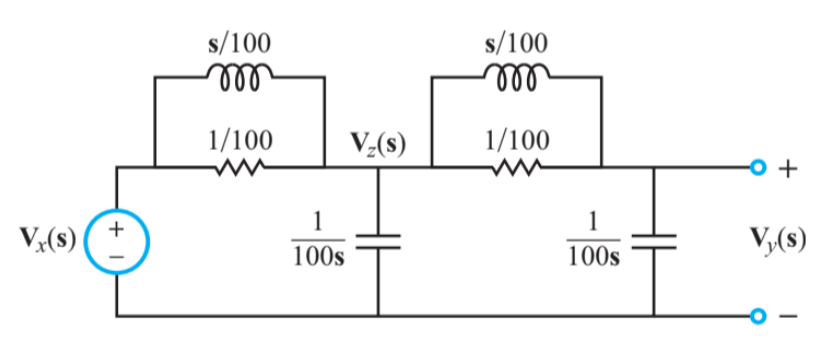

% knowns
syms s t
Zl = s/100;
Zr = 1/100;
Zc = 1/(100*s);
Zrl = (1/Zl+1/Zr)^-1;
Vx = 1;

syms I1 I2 I3 I4 Vz Vy
eqns=[I1 == (Vx-Vz)/Zrl, I2 == (Vz/Zc),I3 == (Vz-Vy)/Zrl,I4 == (Vy/Zc),I1 == I2+I3,I3 == I4];
sol = solve([eqns(1:6)],[I1 I2 I3 I4 Vz Vy]);

% b. transfer function
Vy = sol.Vy

$$Vy = \frac{{\left(s+1\right)}^{2}}{s^{4}+3\,s^{3}+4\,s^{2}+2\,s+1}$$

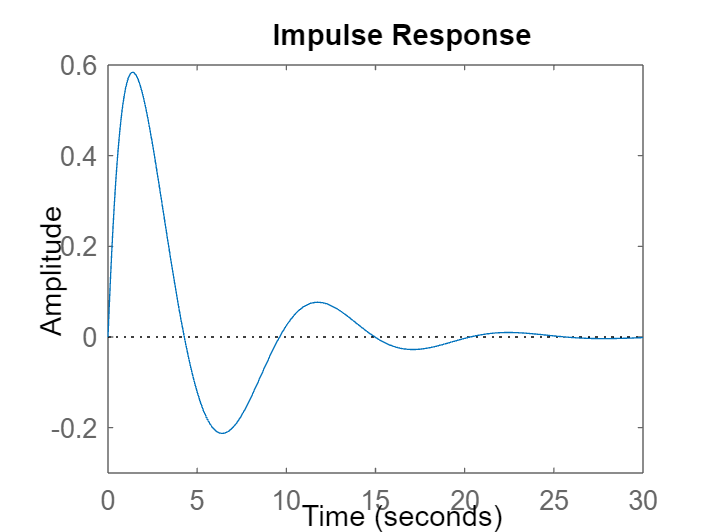


% c. frequency response
[n, d]=numden(Vy);
coeffs_n=fliplr(double(coeffs(n)));
coeffs_d=fliplr(double(coeffs(d)));
Hs_fromtf=tf(coeffs_n,coeffs_d);
impulseplot(Hs_fromtf)